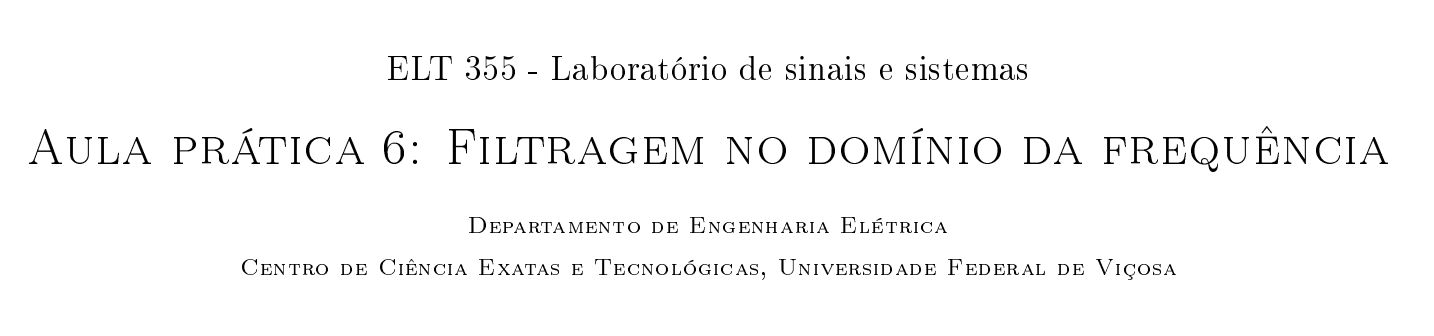

23/06/22

**Aluno:** Déric A. F. de Sales - 96718

clear all; close all; clc;

## Domínio de Tempo <-> Frequência

Transformada de Fourrier de uma soma de senoides com ruído

syms t

x = 0.7*sin(2*pi*500*t) + sin(2*pi*2000*t) % analisando a função

$$x = \frac{7\,\sin\left(1000\,\pi \,t\right)}{10}+\sin\left(4000\,\pi \,t\right)$$

X = simplify(fourier(x)) % e sua transformada de Fourier

$$X = -\frac{7\,\pi \,\left(\delta (w-1000\,\pi )-\delta (w+1000\,\pi )\right)\,\mathrm{i}}{10}-\pi \,\left(\delta (w-4000\,\pi )-\delta (w+4000\,\pi )\right)\,\mathrm{i}$$

clear all; close all; clc;

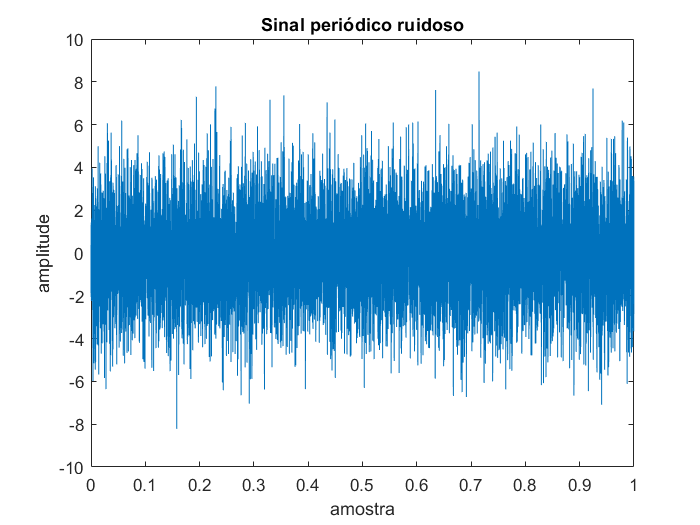

Fs = 8000; % frequência de amostragem
L = 8000; % largura do espectro
t = 0:1/Fs:(L-1)/Fs; % vetor eixo do tempo  

x = 0.7*sin(2*pi*500*t) + sin(2*pi*2000*t) + 2*randn(1,L); % sinal periódico ruidoso

figure; plot(t,x)
title('Sinal periódico ruidoso'); 
xlabel('amostra'); ylabel('amplitude');

Aplicando a Fast Fourier Transform no sinal ruidoso para encontrar suas frequências dominantes

X = fft(x); % convertendo x2 para o domínio da frequência (FFT do sinal)
freq = [-(L/2 - 1) : L/2]*Fs/L; % criando vetor de frequência
pfreq = [0:L/2]*Fs/L; % parte positiva do eixo de frequências

é feito (L/2  - 1) para o caso de a largura do espectro possuir um valor ímpar e acontecer algo como (4025/2) = 2012.5 onde o abs(2012.5) = 2013 podendo gerar um erro de indexação, por isso usa-se fazer (4025/2 - 1) = 2011.5 => abs(2013.5) = 2012.

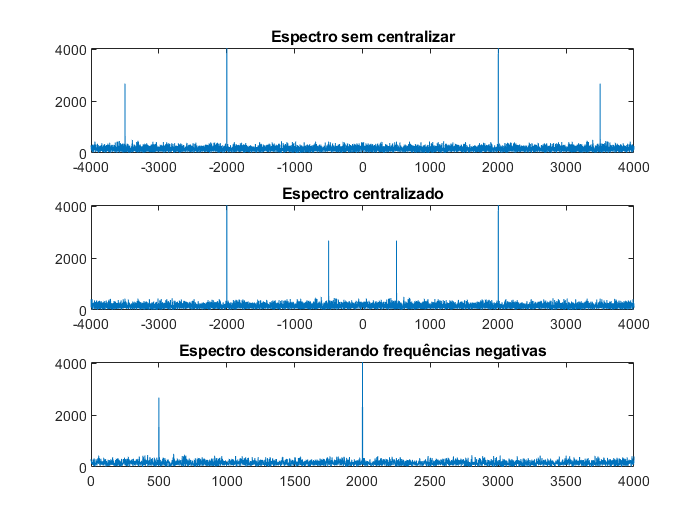

figure;
subplot(3,1,1), plot(freq, abs(X) ); 
title('Espectro sem centralizar')
subplot(3,1,2), plot(freq, abs(fftshift(X)) );
title('Espectro centralizado')
subplot(3,1,3), plot(pfreq, abs( X(1 : L/2 + 1)) ); 
title('Espectro desconsiderando frequências negativas') % parte inédita

Para obter um espectro para o domínio do tempo (transformada de Fourier inversa):

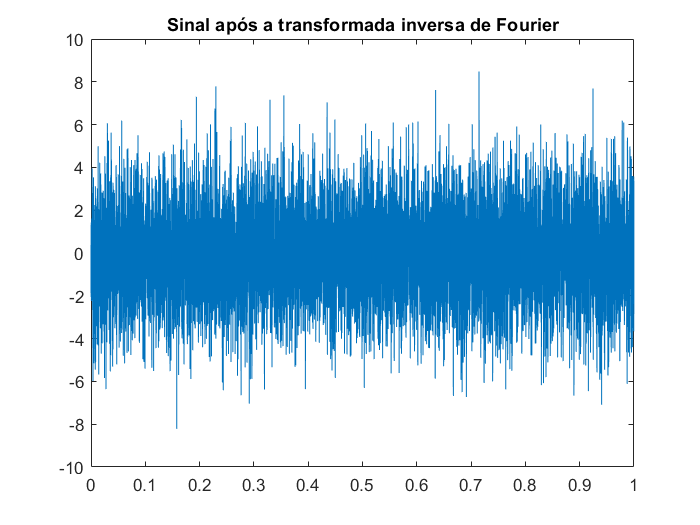

xnew = real(ifft(X));
figure; plot(t,xnew)

title('Sinal após a transformada inversa de Fourier')

### Filtragem passa-baixa

Um filtro ideal passa-baixa segue a seguinte relação:


$$H_{Low}^{ideal} (s) = 

\left\{\begin{array}{@{}ll@{}}

1, |\omega| \leq \alpha \\ 
0, |\omega| > \alpha

\end{array}$$


ou seja, corta frequências maiores que $\alpha$ multiplicanso-as por um ganho 0 e não altera as frequências menores ou iguais à $\alpha$, multiplicando-as por um ganho 1. 

Um filtro real, por sua vez, multiplica um ganho muito baixo para as altas frequências, mas que não é necessariamente 0, que seria o caso ideal.

Através da trasnformada de Fourier é possível converter um sinal no domínio do tempo para o domínio das frequências, aplicar um filtro no domínio da frequência e voltar o sinal para o domínio do tempo com o filtro aplicado. Isso seria equivalente a aplicar o mesmo filtro no domínio do tempo, que pode ser obtido através da transformada de Fourier do filtro usado no domínio da frequência.


$$y(t) = x(t) * h(t) \\
Y(s) = X(s)H(s)$$


Assim, a relação indica que a operação de convolução de x(t) por um filtro h(t), é equivalente à operação de transformar $x(t)$ e $h(t)$ em $X(s)$ e $H(s)$(no domínio da frequência) e simplesmente fazer a sua multiplicação. Ou seja, a multiplicação das funções no domínio da frequência é igual à convolução dessas funções no domínio do tempo.

O filtro passa-baixa então pode ser escrito no domínio da frequência como:


$$H_{Low}(s) = \frac{\alpha}{\alpha + s}; \;\;\; s = + j\omega$$


O código abaixo implementa uma filtragem passa-baixa no sinal x(t) criado no exemplo anterior:

obs.: por definição o filtro é centralizado em relaão à frequência f=0.

a = 1000; % frequencia de corte alpha
Hl = a./(a + j*freq); % filtro passa-baixa Hl
figure;
subplot(2,1,1); plot(freq, abs(Hl)); % resposta em frequência do filtro
xlabel('Frequência (Hz)'); ylabel('Amplitude'); title('Resposta em frequência do filtro');

Para aplicar o filtro à transformada do sinal X na seção anterior, é necessário primeiramente descentralizar a resposta em frequência do filtro:

Hlshift = fftshift(Hl); % centraliza o filtro na frequência zero

De acordo com o help do MATLAB:

`Y = fftshift(X)` rearranges a Fourier transform `X` by shifting the zero-frequency component to the center of the array.

Ou seja, o comando de *Fast Fourier Transform *devolve um vetor onde suas duas metades estão rotacionadas. A função `fftshift `corrige essa questão.

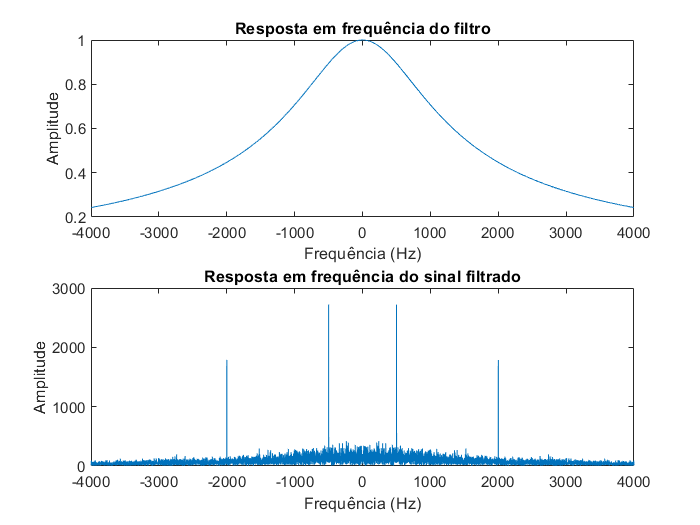

Yl = X.*Hlshift; % filtragem do sinal
subplot(2,1,2); plot(freq, abs(fftshift(Yl))); xlabel('Frequência (Hz)'); ylabel('Amplitude'); title('Resposta em frequência do sinal filtrado');

Resposta no tempo do sinal filtrado:

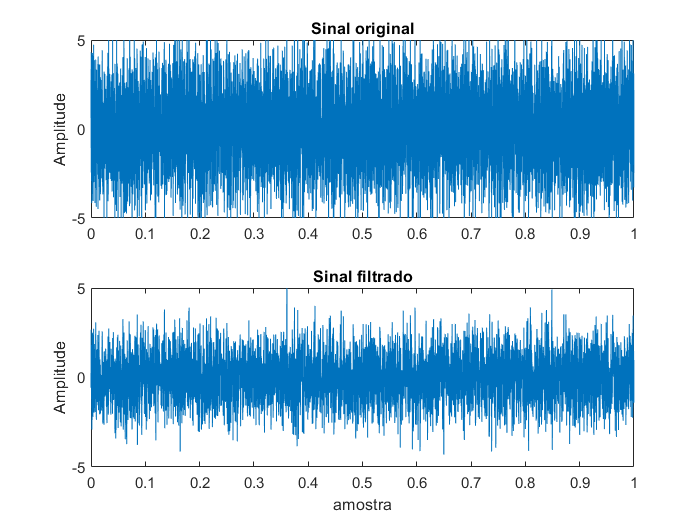

figure
subplot(2,1,1); plot(t,x); ylabel('Amplitude'); title('Sinal original'); axis([0 1 -5 5]);

yl = real(ifft(Yl)); %Transformada Inversa de Fourier do sinal filtrado
subplot(2,1,2); plot(t,yl); ylabel('Amplitude'); title('Sinal filtrado'); axis([0 1 -5 5]);
xlabel('amostra')

### Filtragem passa-alta

É o contrário de um filtro passa-baixa. Um filtro ideal passa-alta segue a seguinte relação:


$$H_{High}^{ideal} (s) = 

\left\{\begin{array}{@{}ll@{}}

0, |\omega| \leq \alpha \\ 
1, |\omega| > \alpha

\end{array}$$


ou seja, corta frequências menores que $\alpha$ multiplicanso-as por um ganho 0 e não altera as frequências maiores que $\alpha$, multiplicando-as por um ganho 1. 

Tem a seguinte relação de transferência:


$$H_{High} = 1 - \frac{\alpha}{alpha + j\omega}$$


onde $\alpha$ é a frequência de corte.

Implementando um filtro para atenuar a frequência de 500 Hz de x(t) :

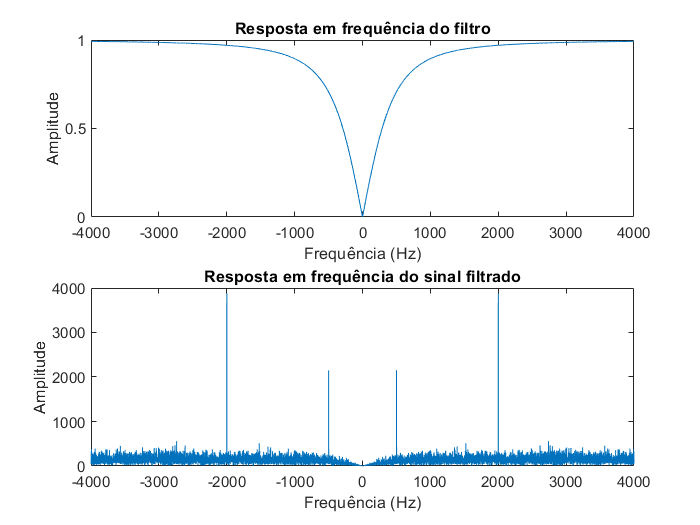

a = 500; % frequência de corte alpha
Hh = 1 - a./(a + j*freq); % filtro passa-altas

figure

subplot(2,1,1); plot(freq, abs(Hh)); % resposta em frequência do filtro
xlabel('Frequência (Hz)'); ylabel('Amplitude'); title('Resposta em frequência do filtro')

Hhshift = fftshift(Hh); % centraliza o filtro na frequência zero
Yh = X.*Hhshift; % filtragem do sinal

subplot(2,1,2); plot(freq, abs(fftshift(Yh))); 
xlabel('Frequência (Hz)'); ylabel('Amplitude'); title('Resposta em frequência do sinal filtrado');

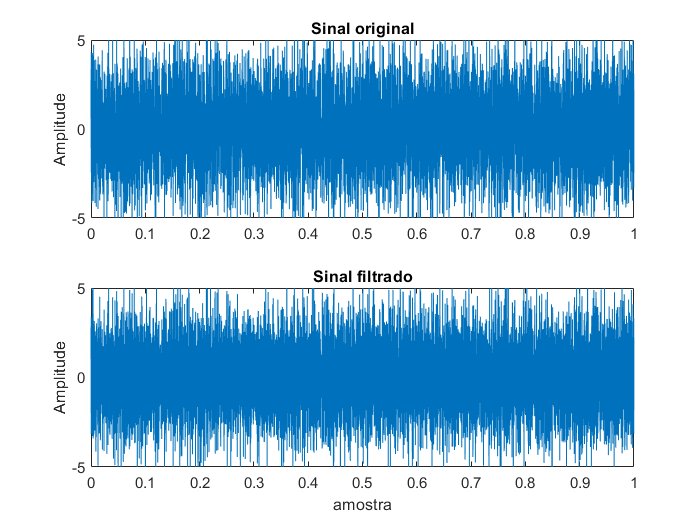

figure

subplot(2,1,1); plot(t,x); ylabel('Amplitude'); title('Sinal original'); axis([0 1 -5 5]);

yh = real(ifft(Yh)); % transformada Inversa de Fourier do sinal filtrado
subplot(2,1,2); plot(t,yh); ylabel('Amplitude'); title('Sinal filtrado'); axis([0 1 -5 5]);
xlabel('amostra')

### Aplicando os filtros em um áudio

clear all; close all; clc;

Serão aplicados àbaixo os filtros passa-baixa e passa-alta em um áudio de castanholas, para estudar seus efeitos no áudio. Áudio original:

[C , Fs] = audioread('castanets44m.wav'); % carrega o arquivo de som
sound(C); % reproduz o arquivo de som

Aplicando um filtro passa-baixas a uma frequência de 500 Hz.

freq = [-(length(C)/2-1):length(C)/2]*Fs/length(C); % vetor de frequências
a = 500; % frequência de corte do filtro
H1 = a./(a+j*freq); % filtro passa-baixas
H1shift = fftshift(H1); % centraliza
Y1 = fft(C).*H1shift'; % realiza a filtragem do sinal
y1 = real(ifft(Y1));  % realiza a transformada inversa de Fourier do sinal
sound(y1); % reproduz o sinal de som

Aplicando um filtro passa-altas a uma frequência de 500 Hz.

a = 500; % frequência de corte do filtro
H2 = 1 - a./(a+j*freq); % filtro passa-altas
H2shift = fftshift(H2);
Y2 = fft(C).*H2shift'; % realiza a filtragem do sinal
y2 = real(ifft(Y2));  % realiza a transformada inversa de Fourier do sinal
sound(y2); % reproduz o sinal de som

Gerando figura comparativa entre os sinais sonoros.

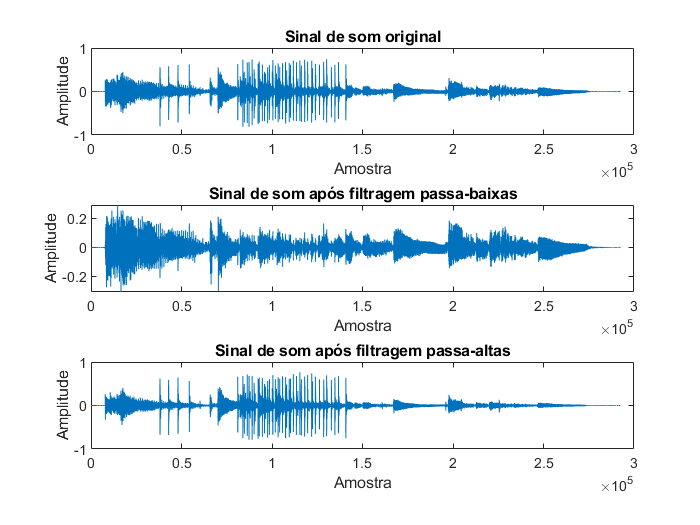

figure;
subplot(3,1,1); plot(C); xlabel('Amostra'); ylabel('Amplitude'); title('Sinal de som original');
subplot(3,1,2); plot(y1); xlabel('Amostra'); ylabel('Amplitude'); title('Sinal de som após filtragem passa-baixas');
subplot(3,1,3); plot(y2); xlabel('Amostra'); ylabel('Amplitude'); title('Sinal de som após filtragem passa-altas');

Aplicando um filtro passa-baixas a uma frequência de 100 Hz.

a = 100; % frequência de corte do filtro
H1 = a./(a+j*freq); % filtro passa-baixas
H1shift = fftshift(H1);
Y1 = fft(C).*H1shift'; % realiza a filtragem do sinal
y1 = real(ifft(Y1));  % realiza a transformada inversa de Fourier do sinal
sound(y1); % reproduz o sinal de som

Aplicando um filtro passa-baixas a uma frequência de 10 Hz.

a = 100000; % frequência de corte do filtro
H2 = 1 - a./(a+j*freq); % filtro passa-altas
H2shift = fftshift(H2);
Y2 = fft(C).*H2shift'; % realiza a filtragem do sinal
y2 = real(ifft(Y2));  % realiza a transformada inversa de Fourier do sinal
sound(y2); % reproduz o sinal de som

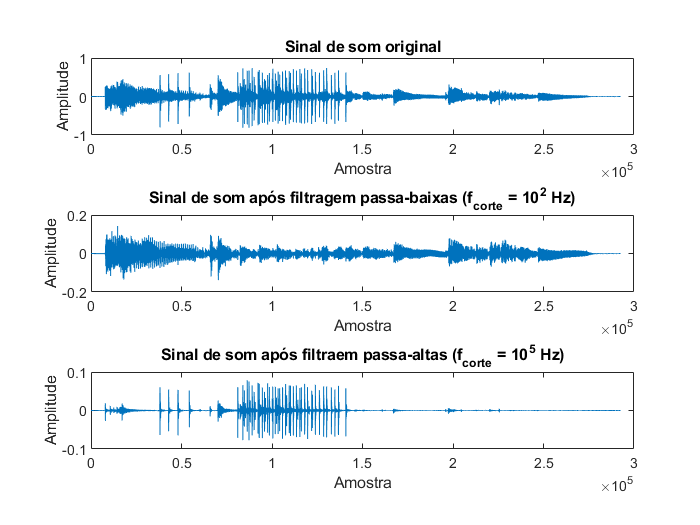

figure;
subplot(3,1,1); plot(C); xlabel('Amostra'); ylabel('Amplitude'); title('Sinal de som original');
subplot(3,1,2); plot(y1); xlabel('Amostra'); ylabel('Amplitude'); title('Sinal de som após filtragem passa-baixas (f_{corte} = 10^2 Hz)');
subplot(3,1,3); plot(y2); xlabel('Amostra'); ylabel('Amplitude'); title('Sinal de som após filtragem passa-altas (f_{corte} = 10^5 Hz)');

### Aplicação dos filtros na eliminação de instrumentos em um áudio

**Objetivo:** ter um som puro do trompete, eliminando o som da bateria. 

clear all; close all; clc;

Há três arquivos de áudio: *bassdrum*, *hatclosed* e o *mixed*. O *mixed* foi criado a partir do *bassdrum* (que é o som de um bumbo), o *hatclosed* (que é o som de um prato de bateria) e a variável *shake*.

Carregando os sinais sonoros:

Fs = 8000; % taxa de amostragem
BD = audioread('bassdrum.wav'); % áudio do bumbo
HC = audioread('hatclosed.wav'); % áudio do prato da bateria
load('shake.mat'); 
[M, F] = audioread('mixed.wav');

Extraíndo seus vetores de frequência:

freq = [-(length(M)/2 - 1):length(M)/2]*Fs/length(M);
fBD = [-(length(BD)/2 - 1):length(BD)/2]*Fs/length(BD);
fHC = [-(length(HC)/2 - 1):length(HC)/2]*Fs/length(HC);
fshake = [-(length(shake)/2 - 1):length(shake)/2]*Fs/length(shake);

Plotando os sinais sonoros no domínio do tempo:

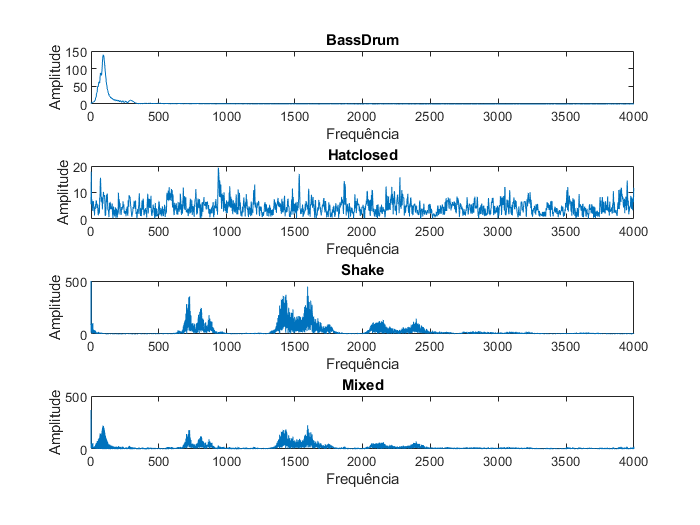

figure

subplot(4,1,1); plot(fBD, abs(fftshift(fft(BD)))); axis([0 4000 0 150]);
xlabel('Frequência'); ylabel('Amplitude'); title('BassDrum');

subplot(4,1,2); plot(fHC, abs(fftshift(fft(HC)))); axis([0 4000 0 20]);
xlabel('Frequência'); ylabel('Amplitude'); title('Hatclosed');

subplot(4,1,3); plot(fshake, abs(fftshift(fft(shake)))); axis([0 4000 0 500]);
xlabel('Frequência'); ylabel('Amplitude'); title('Shake');

subplot(4,1,4); plot(freq, abs(fftshift(fft(M)))); axis([0 4000 0 500]);
xlabel('Frequência'); ylabel('Amplitude'); title('Mixed');

#### Filtro rejeita-faixa para trompete

Testando um filtro rejeita-faixa no áudio *mixed*, a fim de extrair o som da bateria (?)

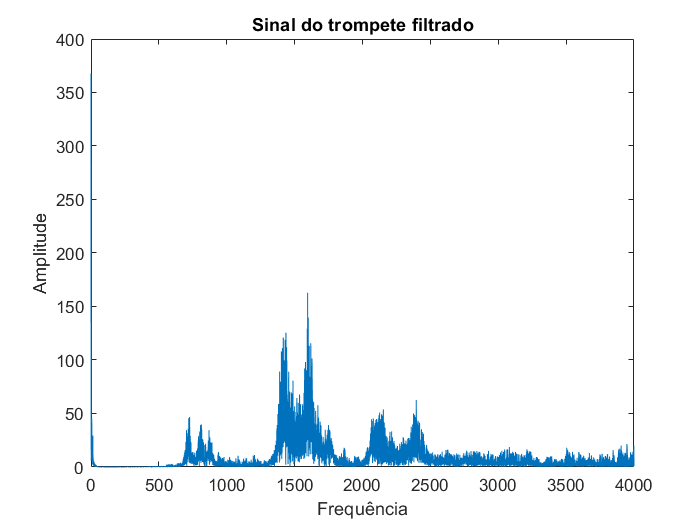

b = 500; % frequência de corte superior
Hb = b./(b+j*freq); % filtro passa-baixa

a = 30; % frequência de corte inferior
Ha = 1 - (a./(a+j*freq)); % filtro passa-alta

H = 1 - Hb.*Ha; % gerando filtro rejeita-faixa
Hshift = fftshift(H); % troca as metades esquerda e direita de H

Y1 = fft(M).*(Hshift.*Hshift.*Hshift.*Hshift.*Hshift.*Hshift)'; % realizando filtragem no áudio mixed
f5 = abs(fftshift(Y1));

figure
plot(freq(length(M)/2:end), f5(length(M)/2:end) ) % plotando sinal filtrado
title('Sinal do trompete filtrado');ylabel('Amplitude');xlabel('Frequência')

y1 = real(ifft(Y1)); % voltando o espectro para o domínio do tempo
sound(y1,F) % reproduzindo o som

#### Filtro passa-baixa para trompete

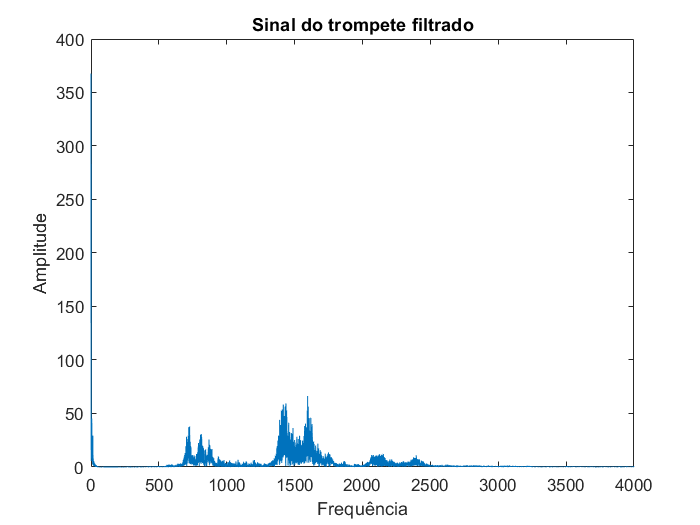

b = 2700; % frequência de corte superior
Hb = b./(b+j*freq); % filtro passa-baixa
H = Hb; 

Hshift = fftshift(H); % troca as metades esquerda e direita de H
Y2 = Y1.*(Hshift.*Hshift.*Hshift.*Hshift.*Hshift.*Hshift)'; % realizando filtragem
f6 = abs(fftshift(Y2));

figure;
plot(freq(length(M)/2:end), f6(length(M)/2:end)) % plotando sinal filtrado
title('Sinal do trompete filtrado');ylabel('Amplitude');xlabel('Frequência')

y2 = real(ifft(Y2)); % voltando o espectro para o domínio do tempo
sound(y2,F) % reproduzindo o som

#### Filtro passa-faixa para trompete

Testando um filtro passa-faixa no áudio *mixed*.

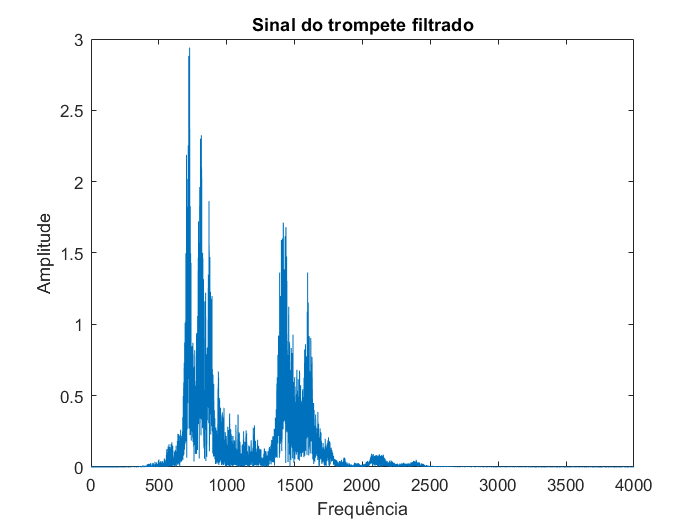

b = 900; % frequência de corte superior
Hb = b./(b+j*freq); % filtro passa-baixa

a = 600; % frequência de corte inferior
Ha = 1 - (a./(a+j*freq)); % filtro passa-alta

H = Hb.*Ha; % gerando o filtro passa-faixa
Hshift = fftshift(H); % troca as metades esquerda e direita de H

Y1 = fft(y2).*(Hshift.*Hshift.*Hshift.*Hshift.*Hshift)'; % realizando filtragem
f5 = abs(fftshift(Y1));

figure;
plot(freq(length(M)/2:end), f5(length(M)/2:end)) % plotando sinal filtrado
title('Sinal do trompete filtrado');ylabel('Amplitude');xlabel('Frequência')


y3 = real(ifft(Y1)); % voltando o espectro para o domínio do tempo
sound(10*y3,F) % reproduzindo o som

#### **Filtro passa-faixa para a bateria**

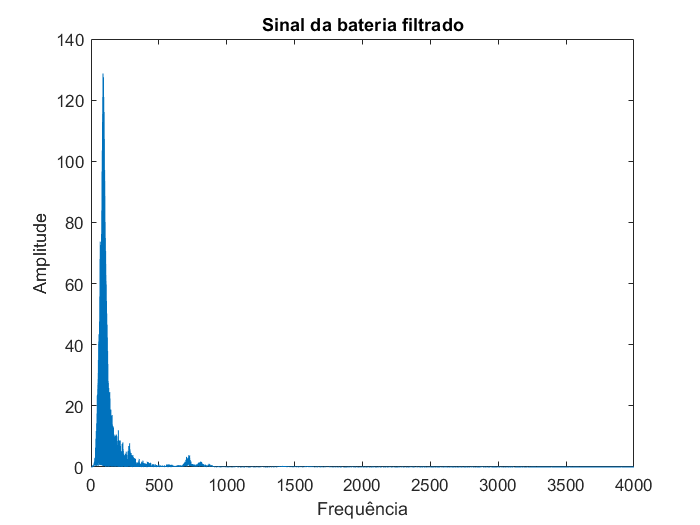

b = 300; % frequência de corte superior
Hb = b./(b+j*freq); % filtro passa-baixa

a = 40; % frequência de corte inferior
Ha = 1 - (a./(a+j*freq));  %filtro passa-alta

H = Hb.*Ha; % gerando o filtro  passa-faixa
Hshift = fftshift(H); % troca as metades esquerda e direita de H

Y3 = fft(M).*(Hshift.*Hshift.*Hshift.*Hshift)'; % realizando filtragem
f7 = abs(fftshift(Y3));

figure;
plot(freq(length(M)/2:end),f7(length(M)/2:end)) % plotando sinal filtrado
title('Sinal da bateria filtrado');ylabel('Amplitude');xlabel('Frequência')

y3 = real(ifft(Y3)); % voltando o espectro para o domínio do tempo
sound(20*y3,F) % reproduzindo o som